## Segundo ensayo del MML

En este segundo ensayo se pretende encontrar una línea recta que optimice la separación de las clases sobre el plano cartesiano, aplicado al Iris dataset. La idea principal yace en los siguientes puntos:

- Ubicar el patrón de la clase 2 cuya posición se encuentre en el extremo inferior o superior derecho del plano.

- Ubicar el patrón de la clase 3 cuya posición se encuentre en el extremo inferior o superior derecho del plano.

Angle = 45

AxisMat =     1.4000    1.5000    1.5000    1.3000    1.5000    1.3000    1.6000    1.0000    1.3000    1.4000    1.0000    1.5000    1.0000    1.4000    1.3000    1.4000    1.5000    1.0000    1.5000    1.1000    1.8000    1.3000    1.5000    1.2000    1.3000    1.4000    1.4000    1.7000    1.5000    1.0000    1.1000    1.0000    1.2000    1.6000    1.5000    1.6000    1.5000    1.3000    1.3000    1.3000    1.2000    1.4000    1.2000    1.0000    1.3000    1.2000    1.3000    1.3000    1.1000    1.3000
    2.5000    1.9000    2.1000    1.8000    2.2000    2.1000    1.7000    1.8000    1.8000    2.5000    2.0000    1.9000    2.1000    2.0000    2.4000    2.3000    1.8000    2.2000    2.3000    1.5000    2.3000    2.0000    2.0000    1.8000    2.1000    1.8000    1.8000    1.8000    2.1000    1.6000    1.9000    2.0000    2.2000    1.5000    1.4000    2.3000    2.4000    1.8000    1.8000    2.1000    2.4000    2.3000    1.9000    2.3000    2.5000    2.3000    1.9000    2.0000    2.300

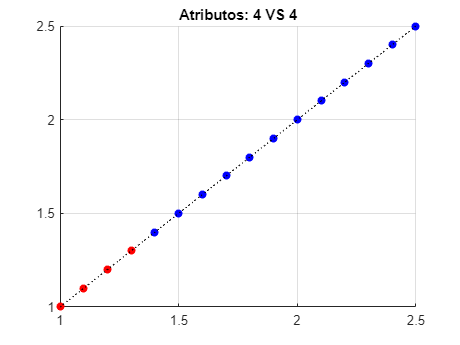

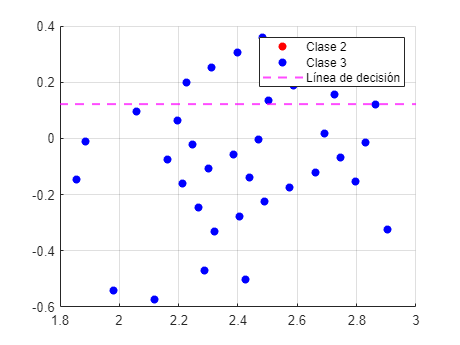

RE = 0.5200

PosC2 = 'Over'

PosC3 = 'Under'

a = 0.1220

C2_Errors = 39

C3_Errors = 13

clc
clear all

dataset = readtable("Iris_C2_C3.csv");
dataset = table2array(dataset(:,1:end-1));
% Separación de clases
C2 = dataset(1:50,:); C3 = dataset(51:100,:);
% Número de atributos
n = size(dataset,2);
% Permutación de atributos
rng(1)
atts = randperm(n);
% Número de atributos a considerar
k = 2;

minimo_Error = 100;
perm = unique(nchoosek(repmat(atts, 1, k), k), 'rows');
par = 16;

for i = par:par %size(perm,1)
    grid on
    hold on
    title(['Atributos: ', num2str(perm(i,1)), ' VS ', num2str(perm(i,2))]);

    % Clase 2
    xC2 = C2(:,perm(i,1));
    yC2 = C2(:,perm(i,2));
    scatter(xC2, yC2, 'or', 'filled')
    
    % Clase 3
    xC3 = C3(:,perm(i,1));
    yC3 = C3(:,perm(i,2));
    scatter(xC3, yC3, 'ob', 'filled')

    % Rotación de vectores originales
    [rC23] = Vec_Rotation(xC2, yC2, xC3, yC3);

    ref_minx = min(min(xC2,xC3));
    ref_miny = min(min(yC2,yC3));

    ref_maxx = max(max(xC2,xC3));
    ref_maxy = max(max(yC2,yC3));
    
    plot([ref_minx, ref_maxx], [ref_miny, ref_maxy], ':k')

    rxC2 = rC23(1,1:50);
    rxC3 = rC23(1,51:100);
    ryC2 = rC23(2,1:50);
    ryC3 = rC23(2,51:100);
    
    %plot(space, aC3 + bC3*space, '-k', 'LineWidth', 1.8)
    figure
    hold on
    grid on
    % Clase 2
    scatter(rxC2, ryC2, 'or', 'filled')
    % Clase 3
    scatter(rxC3, ryC3, 'ob', 'filled')

    [PosC2, PosC3, a, C2_Errors, C3_Errors] = DecisionLine(ryC2, ryC3, dataset, minimo_Error)

    figure
end

- Generar una primera recta oblicua dentro del plano, tomando como referencia un patrón de una clase, y otro patrón de la otra clase.

- Generar una segunda recta oblicua dentro del plano, tomando como referencia un patrón de una clase, y otro patrón de la otra clase.

- Observar cuál de esas dos rectas optimice la separación de las clases, y elegirla.